**Ejemplo de eliminación de ruido**

En este ejemplo se utiliza un filtro adaptativo para eliminar el ruido aleatorio de una señal.

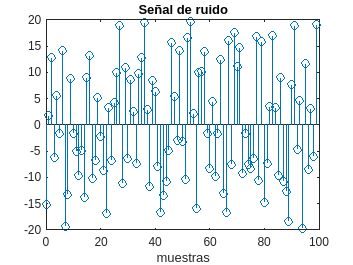

N = 10000;
n = 0:N-1;
n_fact = 40;
%ruido aleatorio
noise = (rand(1,N) * n_fact) - n_fact/2;
figure
stem(n(1:100),noise(1:100))
xlabel('muestras')
title('Señal de ruido')

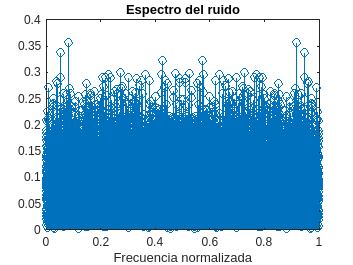

% espectro de frecuencia del ruido
nsk = abs(fft(noise)) / N;

figure
stem(n/N,nsk)
xlabel('Frecuencia normalizada')
title('Espectro del ruido')

Observe que el espectro muestra que la potencia del ruido está distribuida uniformemente en todas las frecuencias. Esta condición dificulta que un filtro convencional pueda eliminar el ruido de forma eficaz, ya que no es posible escoger una frecuencia de corte que rechace el ruido.

Se crea una señal, en este caso periodica. Se aplica el análisis frecuencial para observar sus caracterisitcas. Observe los armónicos, sus amplitudes y fercuencias.

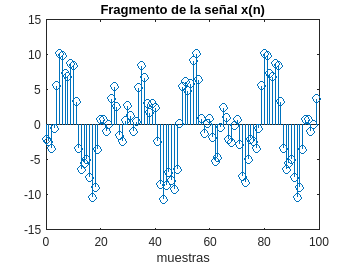

xn = 3*cos(2*pi*1/5*n) - 5*cos(2*pi*1/15*n) + 5*sin(2*pi*1/25*n);

figure
stem(n(1:100),xn(1:100));
xlabel('muestras')
title('Fragmento de la señal x(n)')

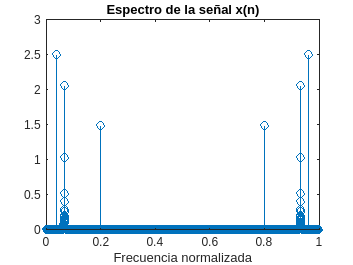


%Espectro de frecuancia
xk = abs(fft(xn)) / N;

figure
stem (n/N,xk)
xlabel('Frecuencia normalizada')
title('Espectro de la señal x(n)')

Se mezclan el ruido y la señal y se aplica el filtro adaptativo. Se usa la señal ruidosa como entrada y ella misma pero con un desplazamiento como señal de referencia.

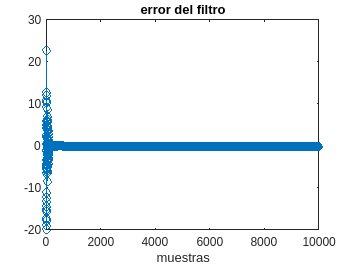

xns = xn + noise;

%ToDo
% Genere el gráfico de la señal con ruido
% y
% Obtenga el espectro de frecuencia
% de la señal con ruido

% Generando la señal con retrazo
delay = 10;
xns_d = circshift(xns,delay);

ord =20;%orden del filtro
pas = 0.000253;
lms=dsp.LMSFilter(ord,'StepSize',pas);
[y,err,w] = lms(xns',xns_d');

figure
stem(n,err)
xlabel('muestras')
title('error del filtro')

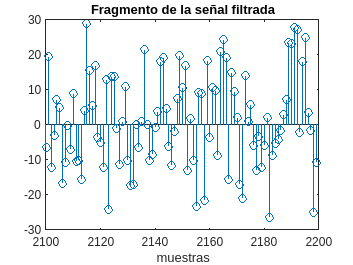


figure
stem(n(2101:2200),y(2101:2200))
xlabel('muestras')
title('Fragmento de la señal filtrada')

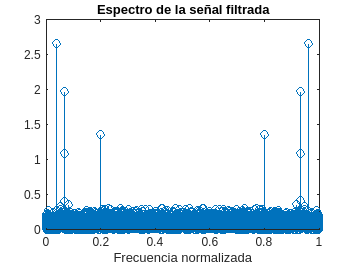


%Espectro de frecuancia
yk = abs(fft(y)) / N;

figure
stem (n/N,yk)
xlabel('Frecuencia normalizada')
title('Espectro de la señal filtrada')

Aplique diferentes condiciones del filtro adaptativo y del nivel de ruido.

Realice comparaciones entre las señales y sus espectros de frecuencia. 

Aplique diferentes condiciones del filtro y del nivel de ruido.

¿Qué puede concluir sobre el desempeño de los filtros adaptativos en esta aplicación?